% Generate sample complex data
rng(42);
N = 100;
p = 2; % model order

% Generate complex AR(2) process
z = complex(randn(N,1), randn(N,1));
for t = 3:N
    z(t) = 0.8*z(t-1) + 0.15*z(t-2) + 0.1*complex(randn(),randn());
end

% Split into training and test
train_data = z(1:end-1);
test_actual = z(end);

% Approach 1: AR on complex values using ar function
mdl_ar = ar(train_data, p);
% For AR models, we need to use predict instead of forecast
ar_pred = predict(mdl_ar, train_data, 1);  % 1 step ahead prediction

% Approach 2: VAR with separated real and imaginary parts
var_data = [real(train_data), imag(train_data)];
mdl_var = varm(2,p);
EstMdl = estimate(mdl_var, var_data);
[Y_pred, ~] = forecast(EstMdl, 1, var_data);
var_pred = complex(Y_pred(1), Y_pred(2));

% Calculate errors
ar_error = abs(test_actual - ar_pred);
var_error = abs(test_actual - var_pred);

% Display results
fprintf('Actual Value: %.4f + %.4fi\n', real(test_actual), imag(test_actual));

Actual Value: 0.3200 + 0.0644i


fprintf('\nAR Model:\n');


AR Model:


fprintf('Predicted: %.4f + %.4fi\n', real(ar_pred), imag(ar_pred));

Predicted: -0.5382 + 0.8672i
Predicted: 0.6144 + 0.6407i
Predicted: 0.4707 + 0.3272i
Predicted: 0.3337 + 0.3916i
Predicted: 0.3939 + 0.3659i
Predicted: 0.3995 + 0.4054i
Predicted: 0.2904 + 0.2245i
Predicted: 0.4393 + 0.5980i
Predicted: 0.6363 + 0.6343i
Predicted: 0.5678 + 0.4556i
Predicted: 0.4394 + 0.5519i
Predicted: 0.6700 + 0.4698i
Predicted: 0.4129 + 0.6062i
Predicted: 0.5604 + 0.5850i
Predicted: 0.5087 + 0.6372i
Predicted: 0.6147 + 0.6413i
Predicted: 0.5437 + 0.5964i
Predicted: 0.6008 + 0.5307i
Predicted: 0.5819 + 0.6577i
Predicted: 0.6340 + 0.6520i
Predicted: 0.6712 + 0.7832i
Predicted: 0.7222 + 0.7064i
Predicted: 0.6871 + 0.5842i
Predicted: 0.4654 + 0.4968i
Predicted: 0.4181 + 0.4182i
Predicted: 0.4304 + 0.3649i
Predicted: 0.3527 + 0.3969i
Predicted: 0.3563 + 0.4008i
Predicted: 0.3671 + 0.2949i
Predicted: 0.3464 + 0.3074i
Predicted: 0.2303 + 0.2254i
Predicted: 0.2692 + 0.3886i
Predicted: 0.3880 + 0.3522i
Predicted: 0.3300 + 0.2103i
Predicted: 0.1360 + 0.3076i
Predicted: 0.2878 +

fprintf('Error: %.4f\n', ar_error);

Error: 0.8588
Error: 0.8418
Error: 0.4426
Error: 0.5164
Error: 0.4710
Error: 0.3671
Error: 0.3719
Error: 0.3183
Error: 0.2492
Error: 0.2750
Error: 0.3639
Error: 0.3756
Error: 0.3296
Error: 0.2535
Error: 0.1970
Error: 0.3329
Error: 0.3657
Error: 0.3583
Error: 0.3323
Error: 0.1517
Error: 0.1826
Error: 0.2466
Error: 0.3700
Error: 0.1498
Error: 0.1350
Error: 0.3064
Error: 0.2694
Error: 0.2701
Error: 0.2024
Error: 0.3378
Error: 0.3042
Error: 0.3545
Error: 0.2797
Error: 0.3538
Error: 0.3989
Error: 0.3216
Error: 0.3708
Error: 0.4476
Error: 0.4298
Error: 0.4374
Error: 0.4603
Error: 0.5297
Error: 0.4395
Error: 0.3912
Error: 0.3745
Error: 0.2870
Error: 0.1622
Error: 0.1771
Error: 0.1031
Error: 0.1513
Error: 0.2859
Error: 0.2536
Error: 0.2344
Error: 0.0775
Error: 0.0363
Error: 0.1044
Error: 0.1373
Error: 0.0823
Error: 0.0439
Error: 0.1462
Error: 0.2090
Error: 0.1901
Error: 0.2286
Error: 0.1781
Error: 0.1274
Error: 0.1685
Error: 0.1350
Error: 0.1932
Error: 0.3087
Error: 0.2481
Error: 0.3375
Error:

fprintf('\nVAR Model:\n');


VAR Model:


fprintf('Predicted: %.4f + %.4fi\n', real(var_pred), imag(var_pred));

Predicted: 0.3014 + 0.1640i


fprintf('Error: %.4f\n', var_error);

Error: 0.1013


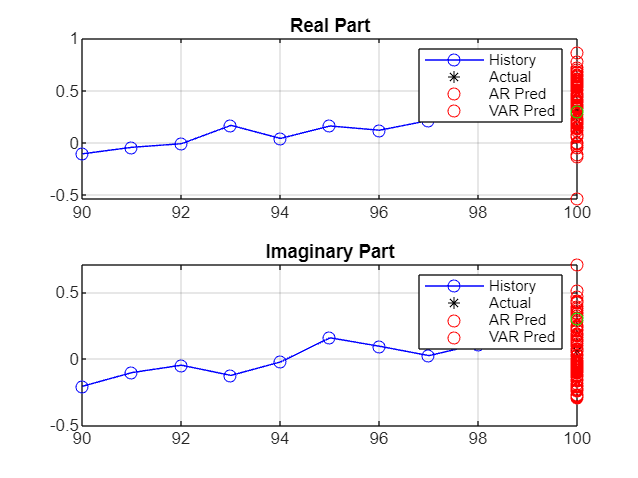


% Plot recent history and predictions
last_points = 10;
t = (N-last_points):N;
figure;
subplot(2,1,1);
plot(t(1:end-1), real(z(end-last_points:end-1)), 'b-o', ...
     t(end), real(test_actual), 'k*', ...
     t(end), real(ar_pred), 'ro', ...
     t(end), real(var_pred), 'go');
title('Real Part');
legend('History', 'Actual', 'AR Pred', 'VAR Pred');
grid on;

subplot(2,1,2);
plot(t(1:end-1), imag(z(end-last_points:end-1)), 'b-o', ...
     t(end), imag(test_actual), 'k*', ...
     t(end), imag(ar_pred), 'ro', ...
     t(end), real(var_pred), 'go');
title('Imaginary Part');
legend('History', 'Actual', 'AR Pred', 'VAR Pred');
grid on;